In today's lecture, we are mostly concerned with calculating or estimating areas. The most likely application in your work will be to calculate probabilities, but the methods we will use are powerful and flexible.

clear
format long

Let's start by using one of those anonymous functions

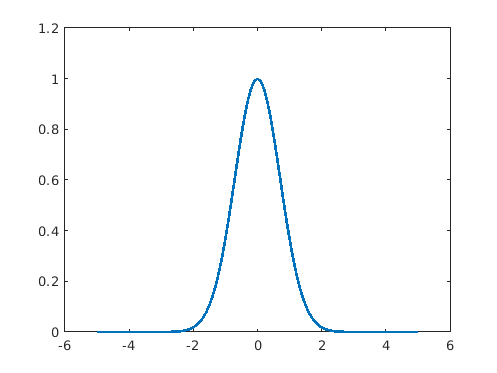

fcn = @(x) exp(-x.^2);

xax = linspace(-5, 5, 101);

plot(xax, fcn(xax), 'linewidth', 2)
axis([-6 6 0 1.2])

# The trapezoid rule

Maybe for a crude approximation, a triangle?

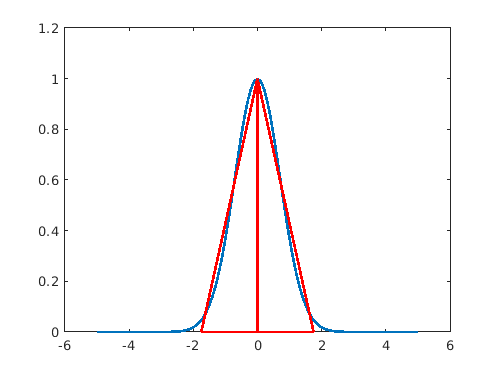

%%
line( ...
    [ 0.00  1.75 -1.75  0.00  0.00], ...  % x values
    [ 1.00  0.00  0.00  1.00  0.00], ...  % y values
    'color', 'r', ...                     % red
    'linewidth', 2)                       % thicc

This triangle has area:

A = 2 * (1.75 * 1 * 0.5)

A =    1.750000000000000


... but this is clearly a very coarse approximation. Let's see if we can do a little better. 

How about some trapezoids?

First put the curve back

%%
xax = linspace(-5, 5, 101);
plot(xax, fcn(xax), 'linewidth', 2)
axis([-6 6 0 1.2])

We'll define some small bins on the horizontal axis

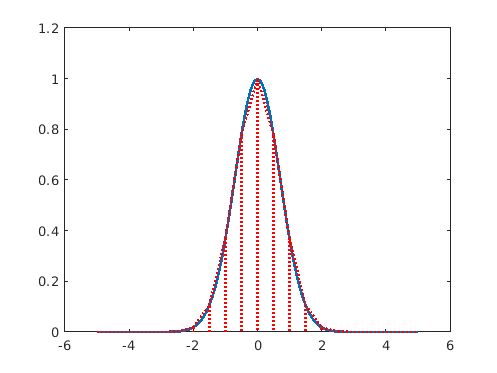

%%
B = 20;                         % number of bins
bins = linspace(-5, 5, B+1);    % edges of B bins
area = zeros(B, 1);             % areas of B bins

for b = 1:B
    x1 = bins(b);               % left edge of this bin
    x2 = bins(b+1);             % right edge of this bin
    y1 = fcn(x1);               % function height on left edge
    y2 = fcn(x2);               % function height on right edge
    h  = (y1 + y2) / 2;         % height of this bin
    line( ...                   % draw the trapezoid
        [x1 x2 x2], ...    % x values
        [y1 y2  0], ...    % y values
        'color', 'r', ...  % red
        'lines', ':', ...  % dashes
        'linew', 2)
    area(b) = h * (x2 - x1);    % area of this bin
end


sum(area)                       % add the areas together

ans =    1.772453850898499


# Gaussian Quadrature

There are many specialized methods for efficient integration.  They only work in very specific circumstances.  One that is very useful is *Gauss-Hermite quadrature*, which is ideal for integrating functions that include a normal distribution as a factor.  For example, consider the expected value of $f\left(x\right)$ if $x\sim \;N\left(\mu ,\sigma^2 \right)$:


$$E(f(x)) = \int_{-\infty}^{+\infty}f(x)p(x)dx\\

p(x) = \frac{1}{\sqrt{2\pi}\sigma}
\exp\left[{-\frac{1}{2}\left(\frac{x-\mu}{\sigma}\right)^2}\right]$$


It turns out this can be well approximated by a weighted average of the function evaluated at specifically chosen points:


$$\int_{-\infty}^{+\infty}f(x)p(x)dx = \frac{1}{\sqrt{\pi}}\sum_k^K w_k
f\left( x_k \sigma\sqrt{2} + \mu \right)$$


Let's see this at work for $$f(x) = x^4$$:

fcn = @(x) x.^4 ;

Let's also set the parameters of the $x$ distribution:

mu = 1;
si = 1;

Those specifically chosen points are called the **quadrature nodes**, and you can just look them up!  These are the weights `w` and nodes `x` for 20 nodes (the values change if you choose a different number of nodes):

w = [ 2.22939E-13  4.39934E-10  1.08607E-7  7.80256E-6  2.28339E-4 ...
      0.00324377   0.0248105    0.109017    0.286676    0.462244   ...
      0.462244     0.286676     0.109017    0.0248105   0.00324377 ...
      2.28339E-4   7.80256E-6   1.08607E-7  4.39934E-10 2.22939E-13];
x = [ -5.38748  -4.60368  -3.94476  -3.34785  -2.78881  ...
      -2.25497  -1.73854  -1.23408  -0.73747  -0.24534  ...
       0.24534   0.73747   1.23408   1.73854   2.25497  ....
       2.78881   3.34785   3.94476   4.60368   5.38748];

And apply the formula:

A = sum(fcn(x * sqrt(2) * si + mu) .* w) ./ sqrt(pi)

A =    9.999998056577313


# Monte Carlo integration

Probably the most common numerical integration technique in our area is a little bit strange. It turns out that often you can approximate integrals by using *random number generation*.

Let's return to the curve we started with: $y = e^{-x^2}$  For this method, we are going to draw a box around the curve, completely capturing it. The box we'll call the **envelope** and since it is rectangular, the area is easy to calculate. Then we are going to randomly select points inside the envelope and count how often they are under the curve. Since the probability of being under the curve must be proportional to the area under the curve, we can now calculate what the area under the curve is, relative to the area of the envelope. An example!

## Monte Carlo Example

Make an anonymous function for the curve and plot it

fcn = @(x) exp(-x.^2);
xax = linspace(-5, 5, 101);
plot(xax, fcn(xax), 'linewidth', 2)
axis([-6 6 0 1.2])

## Define and draw the envelope

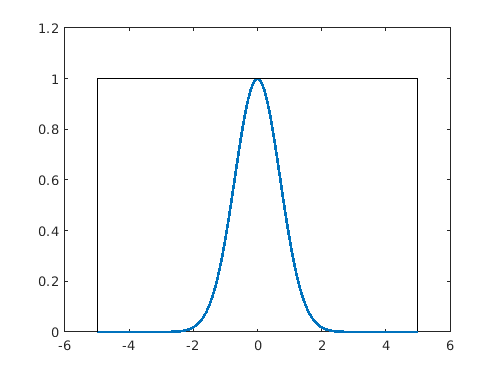

width  = 10;
height =  1;
e_area = (width * height);
line(width/2*[-1 -1 1 1], [0 1 1 0], 'color', 'k')

## Generate a bunch of random points in the envelope

N  = 2000;
rx = ( rand(N, 1) - 0.5 )  *  width;
ry = ( rand(N, 1)       )  *  height;
in = ry < fcn(rx);

## Display the points in the figure

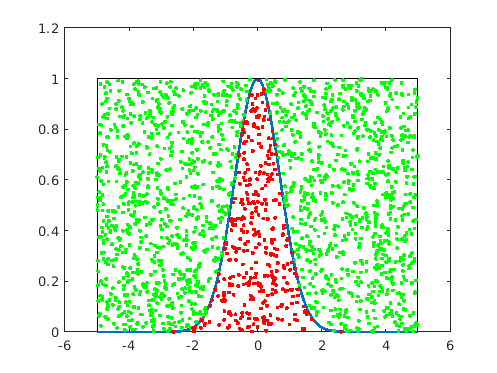

lops = {'marker', '.', 'linestyle', 'none'};
line(rx(~in), ry(~in), 'color', 'g', lops{:})
line(rx( in), ry( in), 'color', 'r', lops{:})

## Count which points are in the area of interest

M  = mean(in) * e_area

M =    1.730000000000000


## Back to the expected value

In many of the same cases as Gaussian quadrature, we can use a Monte Carlo method to approximate an integral, by randomly sampling from the factored distribution and computing the function on those samples:


$$E(f(x)) = \int_{-\infty}^{+\infty}f(x)p(x)dx$$



$$E(f(x)) \approx \frac{1}{n}\sum_{k=0}^n f(x_k) \quad \mbox{with} \quad x_k \sim N(\mu,\sigma^2)
$$


Let's see this at work for $f(x) = x^4$:

fcn = @(x) x.^4 ;

Let's also set the parameters of the $x$ distribution:

mu = 1;
si = 1;

And sample:

N = 1e6;
x = randn(N,1)*si+mu;
mean(fcn(x))

ans =    9.991275390762054


## Other quantities

We now have a large sample to represent the distribution of $x^4$,  We can compute other things, like the probability this is less than some number.  What could $P(x^4<\pi)$ be?

As it turns out, that's

P = mean(fcn(x) < pi)

P =    0.619166000000000


## Y tho?

These Monte Carlo methods clearly take so much more computing power. Why do we use them? The answer is simple. MC methods are easy to implement and widely applicable. You don't have to think about them too much.

We can work to make them more efficient, though.